%% 铝的材料属性
CL = 6.35; % 纵波波速(mm/μs)
CT = 3.13; % 横波波速(mm/μs)
mu = 26; % (MPa)
lambda = 51; % (MPa)
rho = 2.7; % 密度(g/mm3)

%% 几何属性
d = 1; % 板厚(mm)
h = d/2;

fd = 1.5;% 厚频率(MHz·mm)
f = fd/d; % 频率(MHz)
w = f*2*pi; % 圆频率(MHz)
w_sca = w*h/CT; % 无量纲化频率

# 波结构

#### 对称模式

%% 求解频散方程
Fun = @lamb_sym; % 求解实波数
[Kd,~,t] =  get_wavenumber(w_sca,Fun);
%% 求解未知量
Amp_sym = zeros(2,length(Kd));
for ii = 1:length(Kd)
    if Kd(ii) ~= 0
	   [~,A] = lamb_sym(Kd(ii),w_sca);
       Amp_sym(:,ii) = A;
    else
       break
    end
end

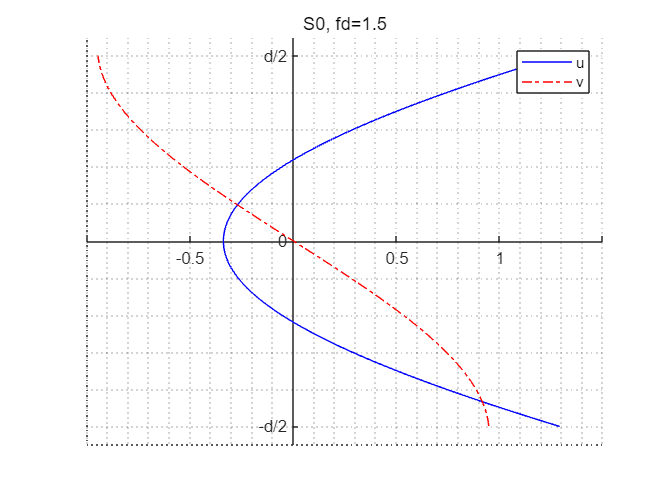

for n = 1:t
A = Amp_sym(:,n);
x = linspace(-h,h,100)';
k = Kd(n)/h;
w = w_sca*CT/h;
p = sqrt(w.^2/CL^2 - k.^2);
q = sqrt(w.^2/CT^2 - k.^2);
u = [1i*k*cos(p*x),  q*cos(q*x)] * A;
v = [-p*sin(p*x), -1i*k*sin(q*x)] * A;

figure
hold on
plot(imag(u),x,'b-'); plot(real(v),x,'r-.');
% plot(zeros(size(x)),x,'k','LineStyle',':') % 辅助直线
hold off

ax1 = gca;
set(ax1,'XAxisLocation','origin','YAxisLocation','origin','YTick',[-h,0,h], ...
	'yticklabels',{'-d/2','0','d/2'},'YLim',[-1.1*h,1.1*h])
title(['S',num2str(n-1),', fd=' num2str(2*f*h)]); 
legend('u','v'); grid minor
end

#### 反对称模式

%% 求解频散方程
Fun = @lamb_asy; % 求解实波数
[Kd,~,t] =  get_wavenumber(w_sca,Fun);
%% 求解未知量
Amp_asy = zeros(2,length(Kd));
for ii = 1:length(Kd)
    if Kd(ii) ~= 0
	   [~,A] = lamb_asy(Kd(ii),w_sca);
       Amp_asy(:,ii) = A;
    else
       break
    end
end

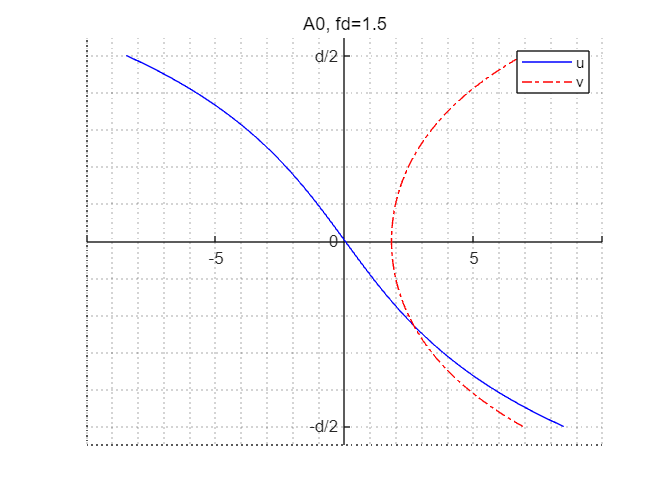

for n = 1:t
A = Amp_asy(:,n);
x = linspace(-h,h,100)';
k = Kd(n)/h;
w = w_sca*CT/h;
p = sqrt(w.^2/CL^2 - k.^2);
q = sqrt(w.^2/CT^2 - k.^2);
u = [1i*k*sin(p*x),  -q*sin(q*x)] * A;
v = [p*cos(p*x), -1i*k*cos(q*x)] * A;

figure
hold on
plot(real(u),x,'b-'); plot(imag(v),x,'r-.');
% plot(zeros(size(x)),x,'k','LineStyle',':') % 辅助直线
hold off

ax1 = gca;
set(ax1,'XAxisLocation','origin','YAxisLocation','origin','YTick',[-h,0,h], ...
	'yticklabels',{'-d/2','0','d/2'},'YLim',[-1.1*h,1.1*h])
title(['A',num2str(n-1),', fd=' num2str(2*f*h)]); 
legend('u','v'); grid minor
end